# **Project Two**

## MAT-350: Applied Linear Algebra

## *Tatiana Gabel*

## *2/14/2023*

# **Problem 1**

Compute $A_{1}$, the **rank-1 approximation of **$A$**. **Clearly state what $A_{1}$ is, rounded to 4 decimal places. Also, **compute** the root-mean square error (RMSE) between $A$ and $A_{1}$.

### Solution

A = [1 2 3; 3 3 4; 5 6 7]

A =      1     2     3
     3     3     4
     5     6     7


[U,S,V] = svd(A)

U =    -0.2904    0.9504   -0.1114
   -0.4644   -0.2418   -0.8520
   -0.8367   -0.1957    0.5115


S =    12.5318         0         0
         0    0.9122         0
         0         0    0.3499


V =    -0.4682   -0.8261   -0.3136
   -0.5581    0.0012    0.8298
   -0.6851    0.5635   -0.4616


%Rank-1 approximation of A
A1 = U(:,1:1)*S(1:1,1:1)*(V(:,1:1).')

A1 =     1.7039    2.0313    2.4935
    2.7243    3.2477    3.9867
    4.9087    5.8517    7.1832


%Root mean square error
RMSE1 = norm(A-A1,'fro')/3

RMSE1 = 0.3257

# **Problem 2**

Compute $A_{2}$, the** rank-2 approximation of **$A$. Clearly state what $A_{2}$ is, rounded to 4 decimal places. Also, **compute** the root-mean square error (RMSE) between $A$ and $A_{2}$. Which approximation is better, $A_{1}$ or $A_{2}$? Explain.

### Solution:

%Rank-1 approximation of A
A2 = U(:,1:2)*S(1:2,1:2)*(V(:,1:2).')

A2 =     0.9878    2.0324    2.9820
    2.9065    3.2474    3.8624
    5.0561    5.8515    7.0826


%Root mean square error
RMSE2 = norm(A-A2,'fro')/3

RMSE2 = 0.1166

%The A2 approximation has a lower average error

**Explain: **

# **Problem 3**

**Compute **the dot product $d_{1}=dot(\mathbf{u}_{1},\mathbf{u}_{2})$.  

**Compute **the cross product $\mathbf{c} =cross(\mathbf{u}_{1},\mathbf{u}_{2})$ and dot product $d_{2} = dot(\mathbf{c},\mathbf{u}_{3})$. Clearly state the values for each of these computations. Do these values make sense? **Explain**.

### Solution:

% Dot product of vectors u1 and u2
% from this we know that u1 and u2 are not orthogonal
d1 = dot(U(:,1:1),U(:,2:2))

d1 = 1.6653e-16

% Cross product of vectors u1 and u2
% This results in another vector that 
% is orthogonal to both u1 and u2
% C is also equal to u3
c = cross(U(:,1:1),U(:,2:2))

c =    -0.1114
   -0.8520
    0.5115


% Dot product of C and u3
d2 = dot(c,U(:,3:3))

d2 = 1.0000

**Explain: **This makes sense, C and u3 are the same and both unit vectors, so their dot product would always be 1. u1,u2,u3 are derived from the singular values and are orthogonal to each other, hence a vector that is orthogonal to u1 and u2 must be in the same direction(or directly opposite direction), in this case it was the first scenario.

# **Problem 4**

Using the matrix $U=[\mathbf{u}_{1} \text{ } \mathbf{u}_{2} \text{ } \mathbf{u}_{3}]$, d**etermine whether or not the columns of **$U$ **span **$\mathbb{R}^{3}$. **Explain your approach.**

### Solution:

% We form a plane between u1 and u2
% if we account for error due to how double's are stored in computer memory
% We can assume this is 0, I will use this logical for the following
% computations
% Since the dot product between u1 and u2, we know that they are orthogonal
% so they are not parallel and can form a plane
testu1u2plane = dot(U(:,1:1),U(:,2:2))

testu1u2plane = 1.6653e-16

% in order to be considered an orthogonal compliment u3 must be orthogonal to both.
% Since the dot product between u1 and u3 is zero they are orthogonal
testu1 = dot(U(:,1:1),U(:,3:3))

testu1 = -2.7756e-17

% Since the dot product between u2 and u3 is zero they are orthogonal
testu2 = dot(U(:,2:2),U(:,3:3))

testu2 = 8.3267e-17

**Explain:** We can define R3 as a direct sum of orthogonal complements. In other words, if a plane formed by two of the vectors is orthogonal to the 3rd vector, then we have a direct sum for R3.

# **Problem 5**

Use the MATLAB imshow() function to load and display the image $A$ stored in the image.mat file, available in the Project Two Supported Materials area in Brightspace. For the loaded image, **derive the value of **$k$ that will result in a compression ratio of $CR \approx 2$. For this value of $k$, **construct the rank-*****k***** approximation of the image**. 

### Solution:

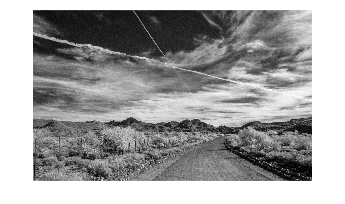

load("MAT 350 Project Two MATLAB Image (1).mat")
figure
imshow(A)

% Finding the value of k for CR=2
CR=2;
m = height(A);
n = width(A);
k = (m * n) / (CR * (m + n + 1));
%rounding
k = round(k)

k = 801


%using this value we find the rank-k approximation
imageA = im2double(A); %converts A to a matrix of doubles
[U,S,V] = svd(imageA);
A801 = U(:,1:801)* S(1:801, 1: 801) * V(:,1:801).';

**Explain: We use the equation for the compression rate, to find k or the number of singular values/columns we need to consider in our approximation. In this case we rounded it to be 801.**

# **Problem 6**

**Display the image and compute** the root mean square error (RMSE) between the approximation and the original image. Make sure to include a copy of the approximate image in your report.

### Solution:

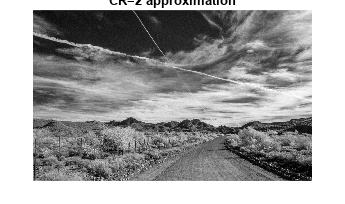

imshow(A801)
title('CR=2 approximation')

% Root mean square error between the original and the approximation
RMSE801 = norm((imgA-A801),'fro')/sqrt(m*n)

RMSE801 = 0.0124

# **Problem 7**

**Repeat** Problems 5 and 6 for $CR \approx 10$, $CR \approx 25$, and $CR \approx 75$. **Explain** what trends you observe in the image approximation as $CR$ increases and provide your recommendation for the best $CR$ based on your observations. Make sure to include a copy of the approximate images in your report.

### Solution:

% We repeat the calculation for a Compression rate of 10
CR = 10;
k = round((m * n) / (CR * (m + n + 1)))

k = 160

% We can reuse the svd values, as it refers to the same matrix
A160 = U(:,1:k)* S(1:k, 1: k) * V(:,1:k).'

A160 =     0.1139    0.1139    0.1190    0.1125    0.1114    0.1012    0.1040    0.0991    0.1084    0.1045    0.1035    0.0979    0.1098    0.1059    0.1067    0.1109    0.1018    0.1240    0.1330    0.1420    0.1340    0.1511    0.1521    0.1496    0.1379    0.1396    0.1371    0.1416    0.1342    0.1211    0.1154    0.1168    0.1198    0.1161    0.1193    0.1169    0.1278    0.1234    0.1201    0.1156    0.1095    0.0967    0.0935    0.0816    0.0730    0.0780    0.0709    0.0715    0.0698    0.0704
    0.1157    0.1141    0.1175    0.1108    0.1109    0.1028    0.1081    0.1024    0.1092    0.1059    0.1038    0.0976    0.1083    0.1063    0.1087    0.1118    0.1034    0.1214    0.1297    0.1368    0.1293    0.1468    0.1503    0.1487    0.1396    0.1388    0.1361    0.1391    0.1311    0.1152    0.1092    0.1098    0.1111    0.1079    0.1124    0.1110    0.1205    0.1168    0.1117    0.1085    0.1027    0.0921    0.0894    0.0827    0.0755    0.0807    0.0739    0.0755    0.0749  

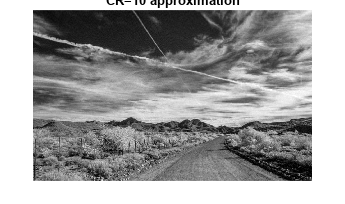

imshow(A160)
title('CR=10 approximation')

% Root mean square error between the original and the approximation
%This is higher than CR=2, but still fairly small
RMSE160 = norm((imgA-A160),'fro')/sqrt(m*n)

RMSE801 = 0.0322

% We repeat the calculation for a Compression rate of 25
CR = 25;
k = round((m * n) / (CR * (m + n + 1)))

k = 64

% We can reuse the svd values, as it refers to the same matrix
A64 = U(:,1:k)* S(1:k, 1: k) * V(:,1:k).'

A64 =     0.0980    0.0955    0.0863    0.0871    0.0861    0.0860    0.0904    0.0933    0.0974    0.1019    0.1050    0.1049    0.1152    0.1124    0.1108    0.1161    0.1113    0.1196    0.1248    0.1222    0.1141    0.1219    0.1246    0.1237    0.1190    0.1229    0.1221    0.1259    0.1225    0.1166    0.1077    0.1037    0.1049    0.1017    0.1001    0.1024    0.1085    0.1114    0.1041    0.1001    0.0946    0.0839    0.0804    0.0775    0.0765    0.0767    0.0782    0.0802    0.0811    0.0804
    0.0988    0.0960    0.0873    0.0879    0.0878    0.0883    0.0925    0.0951    0.0993    0.1036    0.1071    0.1072    0.1170    0.1151    0.1142    0.1201    0.1158    0.1232    0.1285    0.1256    0.1178    0.1266    0.1296    0.1276    0.1224    0.1256    0.1236    0.1266    0.1218    0.1142    0.1042    0.0998    0.1004    0.0971    0.0959    0.0977    0.1043    0.1079    0.1007    0.0971    0.0914    0.0802    0.0757    0.0734    0.0718    0.0723    0.0734    0.0759    0.0770   

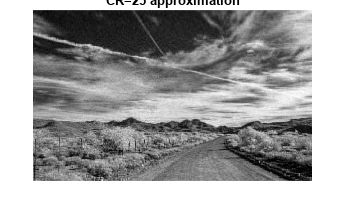

imshow(A64)
title('CR=25 approximation')

% Root mean square error between the original and the approximation
RMSE64 = norm((imgA-A64),'fro')/sqrt(m*n)

RMSE801 = 0.0483

% We repeat the calculation for a Compression rate of 75
CR = 75;
k = round((m * n) / (CR * (m + n + 1)))

k = 21

% We can reuse the svd values, as it refers to the same matrix
A21 = U(:,1:k)* S(1:k, 1: k) * V(:,1:k).'

A21 =     0.1028    0.1005    0.0980    0.0984    0.1002    0.1034    0.1075    0.1065    0.1113    0.1116    0.1150    0.1133    0.1183    0.1204    0.1194    0.1249    0.1253    0.1335    0.1423    0.1493    0.1539    0.1661    0.1719    0.1784    0.1794    0.1861    0.1834    0.1863    0.1794    0.1714    0.1617    0.1549    0.1495    0.1426    0.1410    0.1368    0.1376    0.1370    0.1342    0.1334    0.1300    0.1232    0.1188    0.1137    0.1144    0.1113    0.1110    0.1110    0.1100    0.1086
    0.1040    0.1016    0.0991    0.0995    0.1015    0.1048    0.1088    0.1079    0.1124    0.1124    0.1158    0.1139    0.1188    0.1211    0.1199    0.1251    0.1248    0.1322    0.1404    0.1471    0.1518    0.1643    0.1704    0.1767    0.1775    0.1842    0.1816    0.1846    0.1776    0.1694    0.1597    0.1527    0.1474    0.1406    0.1390    0.1350    0.1358    0.1355    0.1330    0.1323    0.1294    0.1228    0.1182    0.1133    0.1140    0.1112    0.1109    0.1108    0.1096   

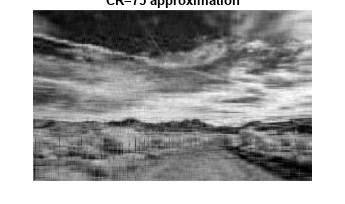

imshow(A21)
title('CR=75 approximation')

% Root mean square error between the original and the approximation
RMSE21 = norm((imgA-A21),'fro')/sqrt(m*n)

RMSE801 = 0.0716

**Explain:  **As CR increases, the quality of the image decreases, and this vertical and horizontal pattern becomes apparent. I also noticed that because CR and k are proportional, when CR is changed by a certain factor, k is changed by that same factor. The RMSE however is not, as it's value appears to increase at a slow rate as the CR increases. For example from CR 2 to 25, the RMSE value increases by 0.0359, but the change from CR 25 to 75(which is a larger gap) is 0.0233. It would be interesting to see if this behavior continues or not.

My recommendation for the best CR would be CR2 or CR10. CR2 is less compressed, but looks better. C10 takes up less space but there is alreadly some visible pixelation and depending on what the site is primarily used for this could drive users away.